# Assignment 02, Computational Astrophysics

This assignment is in two parts. The first part involvs using some available library functions for astronomical calculations. For these assignments, you need to read the given files and understand (1) what is the purpose of the given function and (2) How to use check out the given function with given test data.  It is like a comprehension test; in an examination *unseen* functions would be provided. 

The second part involves developing some familiarity in elementary astronomical concepts (like stellar magnitudes, distance modulus etc) in a computational setting. Common strategies involving the Matlab functions `arrayfunc`, `table`, `array2table`, `sprintf` etc would be demonstrated and applied to these problems. 

In order to get started with the assignments, unzip the contents of the folder and start working on the bundled live script` assignment2.mlx`. Part of the code is already provided for you! Feel free not to adhere to them and write your own code. You can also write a little script every now and then to check out your ideas before including your code in the live-editor) You can also start by going over to the pdf version of the same assignment. Run the full script and Export to pdf after completing the assignment.

% Uncomment and Edit this section after completing the enire assignment and
% before generating the output pdf.

s=date;
Name='Tathagata Karmakar (Roll 122)';
disp( ['Saved on: ' s ' by ' Name ])

Saved on: 09-Feb-2026 by Tathagata (Roll 122)


## Part I

### Conversion of Time formats

#### Question 1 Degrees to DMS

Convert $10^\circ, 15'', 36'''$ to decimals. Use `Ddd.m` (Run help Ddd to know about the usage of the function Ddd. Or you can say `Edit Ddd` to load up Ddd.m in the matlab editor and examine its source code.)

dms_to_ddd = Ddd(10,15,36)

dms_to_ddd = 10.2600

Convert Back into DMS Notation using the function. 

[d,m,s] = DMS(dms_to_ddd)

d = 10

m = 15

s = 36.0000

#### Question 2 DMS to Degrees

Now convert the values: `15.50000, -8.15278, 0.01667, -0.08334` to DMS notation using the `DMS` function. Put these values in a vector and then make use of Matlab's `arrayfun` to apply the function to all elements of the time-vector. The syntax would be something like ` [tD,tM,tS]=arrayfun(@DMS,tvec)`;  Form a matrix out of the columns of `t',tD', tM'` and `tS'`. Display it in tabular format using the `table2array` function. The output should look like the following image. Hints: The table2array function can be called as in `array2table(m,'VariableNames',CNames), w`here `CNames` is a cell array containing the column headers of the table.

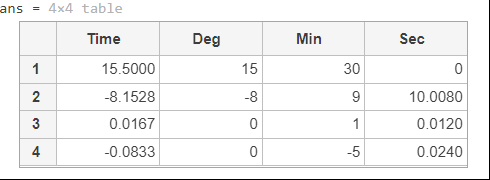

clear ;

tvec = [15.50000, -8.15278, 0.01667, -0.08334];
[tD,tM,tS] = arrayfun(@DMS,tvec);
m = [tvec',tD',tM',tS'];
CNames = ["Time", "Deg", "Min", "Sec"];

array2table(m,'VariableNames',CNames)

ans = 4×4 table
      Time      Deg    Min     Sec  
    ________    ___    ___    ______

        15.5    15     30          0
     -8.1528    -8      9     10.008
     0.01667     0      1      0.012
    -0.08334     0     -5      0.024


#### Question 3 Julian Day

The function Mjday returns the number of (modified) Julian days. Read the function definition and find the number of Julian days elapsed at the following points of time: Dec 12, 1971 02:31:17 PM, Feb 09, 2023, 08:30:11 AM. How many days passed between these two space time points? You may find it useful to change to format bank while working out the answer (revert back afterwards to the normal output format). 

% Uncomment and write your code here (replace the "---" by something appropriate
 d1=Mjday(1971, 12, 12, 14, 31, 17);
 d2=Mjday(2023, 2, 9, 8, 30, 11);
 disp(['d1=',num2str(d1)]); disp(['d2=',num2str(d2)]);disp(['ndays=',num2str(d2-d1)]); 

d1=41297.6051
d2=59984.3543
ndays=18686.7492


## Part II

### Common Strategies

We discuss and demonstrate a set of common strategies for the Matlab live-script interface which *also* works with Matlab scripts, i.e these strategies are not interface specific but involve the use of named and unnamed (anonymous)  `@` function handles and some functions like `arrayfun` for generalising a function originally devised for scalar inputs to accept list inputs. Some aspects of producing console output in the form of tables using `table`, `array2table`,` num2str, disp` and `sprintf`  (a function that copies a formatted text string to a string variable) have also been touched upon. 

According to  [Matlab documentation](https://in.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) an anonymous function is a function that is *not* stored in a program file, but is associated with a variable whose data type is [`function_handle`](https://in.mathworks.com/help/matlab/ref/function_handle.html).  Anonymous functions can accept multiple inputs and return one output. They can contain only a single executable statement. We have seen (in the above problems) how a function written as an external file can also be used as function handle). One straightforward example might be that of a function that computes the area of a rectangle:

areaRect = @(x,y) x*y;
a=2.6; b= 9.5; 
xArea= areaRect(a,b);
disp(['The area is ' num2str(xArea) ' m^2'])

The area is 24.7 m^2


It is possible to calculate the area of several rectangles by threading `arrayfun `over two lists containing the two sides of the rectangles.

aa=[1.7 2.9 3.6 8.7]; 
bb=[11.2 88.7 123.4 881.8];
xArea = arrayfun(areaRect,aa,bb);
sxArea=strtrim( sprintf('%g ', xArea) );
disp(['The areas are ', sxArea, ' sq m'])

The areas are 19.04 257.23 444.24 7671.66 sq m


Anonymous functions are so called as they do not really need a name, e.g the following code has the same effect although no names have been assigned to the algorithm that calculates the area.

disp( ['The areas are ', ...
    strtrim( sprintf('%g ', arrayfun(@(x,y) x*y,aa,bb) ) ), ...
    ' sq m'])

The areas are 19.04 257.23 444.24 7671.66 sq m


### Magnitudes and such

#### Question 4  Magnitudes

For a revision of the concept of stellar magnitudes see this [ksu](https://www.phys.ksu.edu/personal/wysin/astro/magnitudes.html) page (local pdf copy archived [here](matlab:open('ksu.pdf'))). Make sure you understand all the connections. Now work out the following problems.

**Relative Magnitude**: *Define* an anonymous function (of the brightnesses of two objects) named `relmag` in your workspace (Make it a function of the brightnesses of the two objects) which would calculate the relative magniture of objects whose brightness ratios vary between 1 to 500 in steps of 5. 

 Display only 5 representative values of the Relative Magnitudes vs their Brightness ratios including the first and the last values in a table. 

relmag = @(x,y) -2.50*log10(y/x);
B2=1:5:100;
B1=ones(size(B2));
xMags=arrayfun(relmag,B2,B1);
xMagsDisp=xMags(1:4:end);
B2Disp=B2(1:4:end);
m=[B2Disp' xMagsDisp'];
CNames={'Brt. Ratios', 'Magnitudes'};
array2table(m,'VariableNames',CNames)

ans = 5×2 table
    Brt. Ratios    Magnitudes
    ___________    __________

         1                0  
        21           3.3055  
        41            4.032  
        61           4.4633  
        81           4.7712  


**Absolute Magnitude:** Now Define an anonymous function (of the relative magnitude *m* and distace *d* (in pc) ) named `absmag` in your workspace which would calculate the absolute magniture of objects of relative magnitude m = -2 and situated between 10 to 1000 pc. This time create spaced arrays of spacing 8 and wrap the tabular output within a `disp`. (Note the difference in output)

distArr=10:8:1000;
mag = -2 * ones(size(distArr));
absmag = @(x,mag) mag - 2.50*log10((x/10).^2);

xMags=arrayfun(absmag,distArr,mag);
xMagsDisp = [xMags(1:6) xMags(end-5:end)];
distDisp = [distArr(1:6) distArr(end-5:end)];

m=[distDisp' xMagsDisp'];
CNames={'Distance(pc)', 'Magnitudes'};
disp(array2table(m,'VariableNames',CNames))

    Distance(pc)    Magnitudes
    ____________    __________

         10               -2  
         18          -3.2764  
         26          -4.0749  
         34          -4.6574  
         42          -5.1162  
         50          -5.4949  
        954          -11.898  
        962          -11.916  
        970          -11.934  
        978          -11.952  
        986          -11.969  
        994          -11.987  



#### Question 5 Distance Modulus

The Distance modulus $\mu$ is a measure of distance to a celestial object. It is defined as


$$\mu = m -M$$


An object with a distance modulus of 0 is exactly 10 parsecs away. If the distance modulus is negative, the object is closer than 10 parsecs, and its apparent magnitude is brighter than its absolute magnitude. If the distance modulus is positive, the object is farther than 10 parsecs and its apparent magnitude is less bright than its absolute magnitude. Verify that $\mu(d) = 5 \log_{10} d - 5$ and find the distances $d$ (in pc) for $\mu \in (-4,-3,\ldots 5) \cup \lbrace 10, 20\rbrace$. Display them in a table. 

**Procedure:**  Define functions `mu(d)` for calculating the distance modulus as a function of distances in pc and and `lg10d(x)`  for calculating the distance from the distance modulus $x$ first. Then construct a list `muvec` for holding the distance moduli and calculate the distances in another list `dmodvec` using `arrayfun`. 

% function for mu
function distMod = mu(d)
    distMod = (5.0*log10(d)) - 5;
end

% function for distance
function dist = lg10d(x)
    dist = 10.^((x+5)/5);
end

%muvec = -4:1:5;
muvec = [-4, -3, -2, -1, 0, 1, 2, 3, 4, 5, 10, 20];
dmodvec = arrayfun(@lg10d, muvec);

table1 = [muvec', dmodvec'];

Cnames1 = {'Given, Distance Modulus', 'Distance (in pc)'};

array2table(table1, 'VariableNames', Cnames1)

ans = 12×2 table
    Given, Distance Modulus    Distance (in pc)
    _______________________    ________________

              -4                    1.5849     
              -3                    2.5119     
              -2                    3.9811     
              -1                    6.3096     
               0                        10     
               1                    15.849     
               2                    25.119     
               3                    39.811     
               4                    63.096     
               5                       100     
              10                      1000     
              20                     1e+05     



muArr = arrayfun(@mu,dmodvec);
table2 = [dmodvec', muArr'];

Cnames2 = {'Distance (in pc)', 'Verified, Distance Modulus'};
array2table(table2, 'VariableNames', Cnames2)

ans = 12×2 table
    Distance (in pc)    Verified, Distance Modulus
    ________________    __________________________

         1.5849                     -4            
         2.5119                     -3            
         3.9811                     -2            
         6.3096                     -1            
             10                      0            
         15.849                      1            
         25.119                      2            
         39.811                      3            
         63.096                      4            
            100                      5            
           1000                     10            
          1e+05                     20            


Suppose you were viewing the Sun from a planet orbiting another star 40 pc away. What would the Sun's apparent magnitude be? (The Sun has absolute magnitude *M* = +4.8). Ans: 7.8

**Procedure:** Calculate the distance modulus first. Then find the apparent magnitude from the distance modulus and absolute magnitude. 

distance = 40; % in pc
distMod = mu(40);

AbsMag_Sun = 4.8;

apparentMag = AbsMag_Sun + distMod;

disp(['Distance modulus of Sun from a distance of 40 pc is : ',num2str(distMod), ...
    newline 'Apparent Magnitude of Sun : ',num2str(apparentMag)])

Distance modulus of Sun from a distance of 40 pc is : 3.0103
Apparent Magnitude of Sun : 7.8103


### References

(1) For a revision of the concept of stellar magnitudes see this [ksu](https://www.phys.ksu.edu/personal/wysin/astro/magnitudes.html) page (local pdf copy archived [here](matlab:open('ksu.pdf')))

(2) Las Cumbres Observatory [page](https://lco.global/spacebook/distance/what-is-distance-modulus/) on distance modulus 

(3) Wikipedia [entry](https://en.wikipedia.org/wiki/Distance_modulus) on distance modulus 